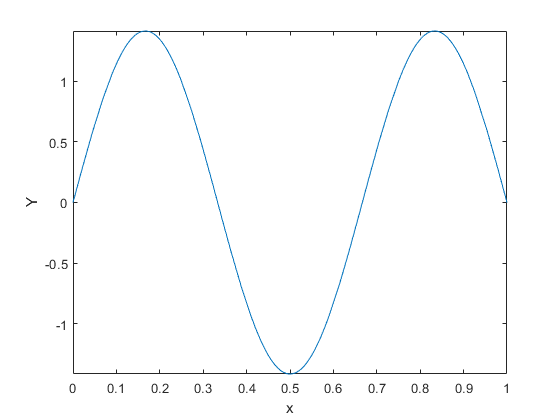

%infinite square well with 0<=x<=a

%       |     |
%       |     |
% v=inf | v=0 | v=inf
%       |_____|
%       0     a  


% Y_n(x)=sqrt(2/a)*sin(n*pi*x/a)  Energy eigenfunctions at the position
% space

syms a n x h m t real



a=1;
n=3;
m=1;
h=1;

Yx=@(n) sqrt(2/a)*sin(n*pi*x/a); 
fplot(Yx(n),[0 1])
xlabel('x')
ylabel('Y')

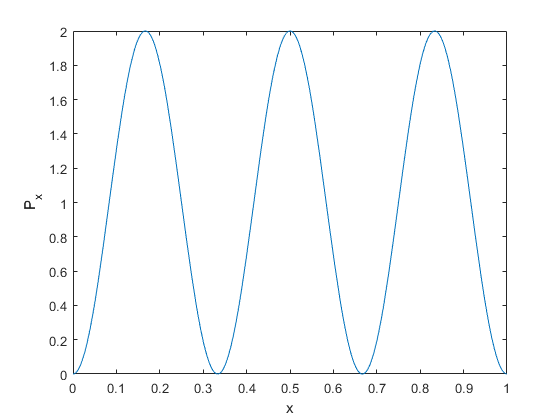


Px=Yx(n)'*Yx(n); %Probability density of position
fplot(Px,[0 1])
xlabel('x')
ylabel('P_x')


%integrate probability density to see whether it equals to unity
int(Px,0,1)

$$ans = 1$$

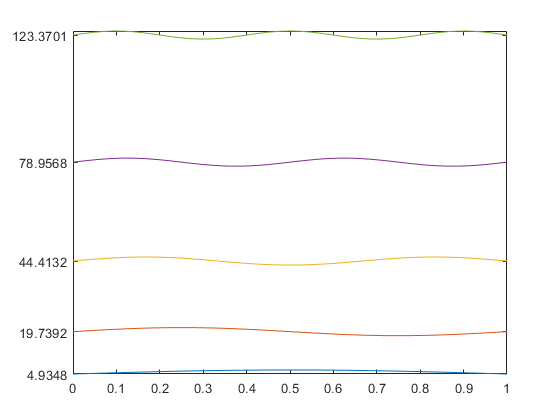


E=@(n) n^2*pi^2*h^2/(2*m*a^2); %Energy of nth quanta


% wavefunctions at allowed energy levels
for n=1:5
    fplot(Yx(n)+E(n),[0 1])
    hold on
end
yticks([E(1) E(2) E(3) E(4) E(5)])
%xticklabels({'0','\pi/2','\pi','3\pi/2','2\pi','5\pi/2','3\pi'})
hold off

%Yxt=Yx(n)*exp(-1i*E(n)*t/h) %Adding time dependence to probability amplitude

%drawing the real and imag part of time dependent probability amplitude
% for tt=0:20
%     fplot(real(subs(Yxt,t,tt)),[0 1])
%     hold on
%     fplot(imag(subs(Yxt,t,tt)),[0 1])
%     axis([0 1 -1.5 1.5])
%     pause(.2)
%     hold off
% end

%If probability amplitude wavefunction could be separated into 
%spatial and temporal(time) parts probability density would not change
%so Pxt is stationary while Yxt not


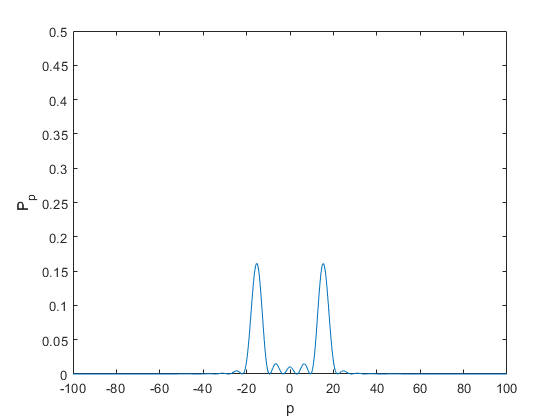

syms p real

%Fourrier transform of Yx to Yp
f=Yx(n)*(exp(1i*p*x/h)/sqrt(pi*a*h)); %<p|x><x|Y>
Yp=int(f,x,0,a); 

Pp=Yp'*Yp; %Probability density of momentum
fplot(Pp,[-100 100])
axis([-100 100 0 .5])
xlabel('p')
ylabel('P_p')

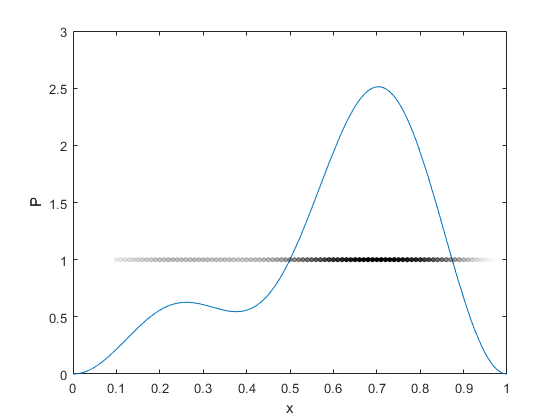

%Composite wavefunction
%Yc=A*Y(n1)+B*Y(n2) where A^2+B^2=1

%Adding time dependence to probability amplitude
Yxt=@(n)Yx(n)*exp(-1i*E(n)*t/h);

%Amplitude of different wavefunctions
A=1/sqrt(2);
B=sqrt(1-A^2);

%Composite wavefunctions n1=1 and n2=2
Yc= A*Yxt(1)+B*Yxt(2);
Pc=Yc'*Yc; %Probability amplitude of composite wavefunction
Pc=simplify(Pc,'Steps',100);

%Plot for tt
for tt=0:.01:1
    Pcn=subs(Pc,t,tt);
    fplot(Pcn,[0 1])
    axis([0 1 0 3])
    hold on
    
    %plot dots
    %their transparency is related to their probability
    xx=.1:.01:1;
    alphadata=subs(Pcn,x,xx)./3;
    yy=ones(1,length(xx));
    
    s=scatter(xx,yy);
    s.Marker='o';
    s.SizeData=10;
    s.AlphaData=alphadata;
    s.MarkerFaceAlpha='flat';
    s.MarkerFaceColor='k';
    s.MarkerEdgeColor='k';
    s.MarkerEdgeAlpha='flat';
    
    
    
    pause(.1)
    hold off
end
xlabel('x')
ylabel('P')

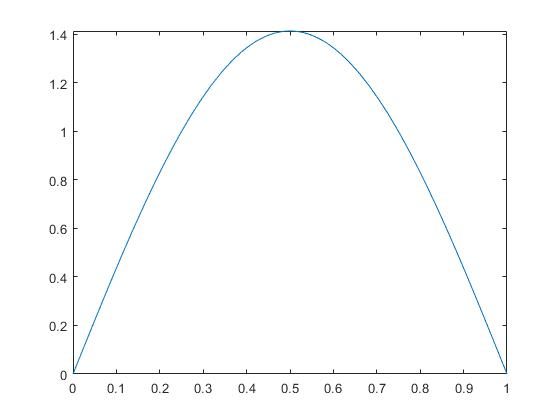


%Plot of Y1(x)
fplot(Yx(1),[0 1])

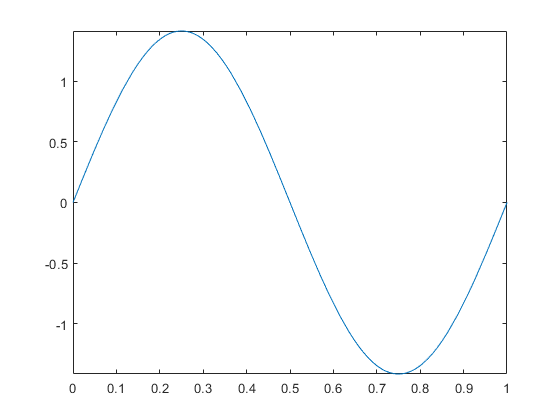

%Plot of Y2(x)
fplot(Yx(2),[0 1])

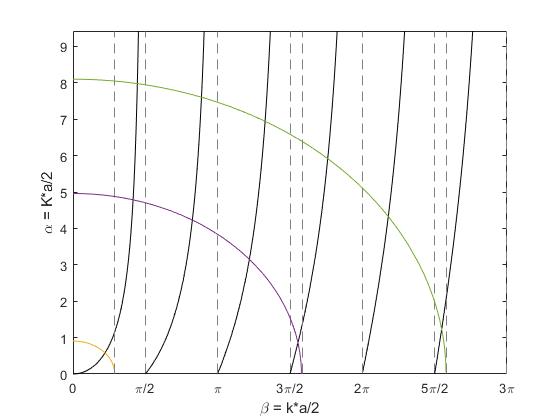

clear
close
syms x V0

% m=9.11*e-31 kg                electron mass
% h=1.0546*e-34 Js              reduced Planck constant
% 1 eV=1.60217662*e-19 J
% J=kg*m^2/s^2

me=9.11*10^(-31);           %kg
h=1.0546*10^(-34);          %kg*m^2/s
a=2.5*10^(-10);             %m
eV=1.60217662*10^(-19);     %J=kg*m^2/s^2

%Finite square well with -a/2<=x<=a/2

%          _V=V0_                ___V=V0__
%                |              |
%  C*exp(K*x)    |  A*cos(k*x)  |   C*exp(-K*x)   even
%                |              |
%                |  B*cos(k*x)  |  -C*exp(-K*x)   odd
%                |              |
%                |______V=0_____|
%             -a/2              a/2
%
% k=2*pi/lambda         wave number
% k=sqrt(2*m*E/h^2)
% K=sqrt(2*m*(V0-E)/h^2)
% even solution (aK/2) = (ak/2)*tan(ak/2) -> alpha= beta*tan(beta)
% odd solution  (aK/2) =-(ak/2)*cot(ak/2) -> alpha=-beta*cot(beta)
% (aK/2)^2+(ak/2)^2 = (a^2/2)*(m*V0/h^2)
% (alpha)^2+(beta)^2 = (a^2/2)*(m*V0/h^2)
% So every value of V0 can be represented by a circle
% Allowed energy levels are at the intersection of this circle and
%   beta*tan(beta) or -beta*cot(beta)
%   E=2*h^2*(k*a/2)^2/(m*a^2)=2*h^2*(beta)^2/(m*a^2)
% Radius of this circle increase with a, m and V0
% Thus wider or deeper well means more allowed energy levels
% Since K=sqrt(2*m*(V0-E)/h^2) the radius of this circle could be 
%   determined by equating E to 0 (k=0) and multiplying this equation
%   by a/2 so that alpha=a*K/2=(a/2)*sqrt(2*m*(V0)/h^2). In this case
%   R=(a/2)*sqrt(2*m*(V0)/h^2)

R=(a/2)*sqrt(2*me*(V0)/h^2); %=a*K/2 @k=0


%plot beta*tan(beta) where x=beta=ka/2
fplot(x*tan(x),[0 3*pi],'Color','k')
xticks(0:pi/2:3*pi)
xticklabels({'0','\pi/2','\pi','3\pi/2','2\pi','5\pi/2','3\pi'})
axis([0 3*pi 0 3*pi])
hold on

%plot -beta*cot(beta) where x=beta
fplot(-x*cot(x),'Color','k')
xlabel('\beta = k*a/2')
ylabel('\alpha = K*a/2')


V=[2*eV 60*eV 160*eV];

%plot circle for different V0
for v=V
    r=subs(R,V0,v);
    fplot(sqrt(r^2-x^2))
    hold on
end




% [X, Y]=meshgrid(linspace(0,3*pi,50));
% Z=sqrt(X.^2+Y.^2);
% contour(X,Y,Z,0:pi/2:3*pi,'ShowText','on','LineStyle','--','Color','r')


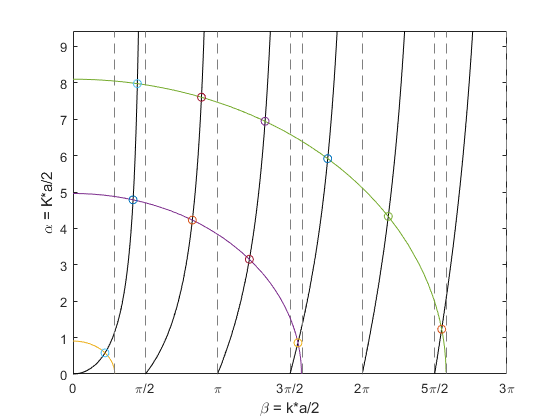

% Here we find the intersection points
% Remember that x=k*a/2 and y=K*a/2


%even solutions for different V0
evenkKdiffV0={};

%odd solutions for different V0
oddkKdiffV0={};


jj=1;

for v=V
    evenkK=[];
    oddkK=[];
    %radius for V0
    r=subs(R,V0,v);
    assume(x,'positive')
    %intersection for even solutions
    eqn=sqrt(double(r)^2-x^2)==x*tan(x);
    for ii=[5*pi/4:pi:9*pi/4 3*pi/8]
        %since analytical solution could not be found we use vpasolve
        solx=vpasolve(eqn,x,ii);
        if ~isempty(solx)
            soly=sqrt(r^2-solx^2);
            plot(solx,soly,'o')
            evenkK=[evenkK; [solx soly]];
        end
    end
    
    %intersection for odd solutions
    eqn=sqrt(double(r)^2-x^2)==-x*cot(x);
    for ii=3*pi/4:pi:3*pi
        solx=vpasolve(eqn,x,ii);
        if ~isempty(solx)
            soly=sqrt(r^2-solx^2);
            plot(solx,soly,'o')
            oddkK=[oddkK; [solx soly]];
        end
    end
    
    %Since evenkK=k*a/2 we multiply by 2/a to find k
    evenkKdiffV0{jj}=evenkK*2/a;
    if ~isempty(oddkK)
        oddkKdiffV0{jj}=oddkK*2/a;
    end
    jj=jj+1;
end

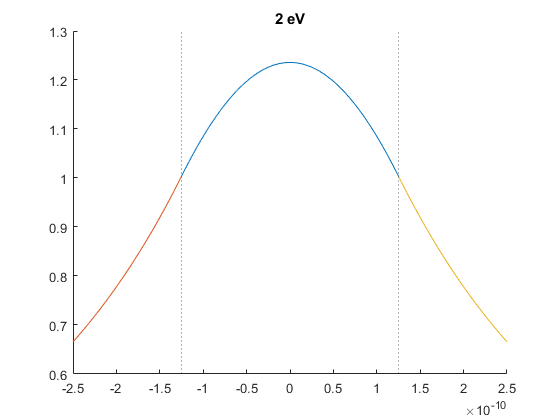

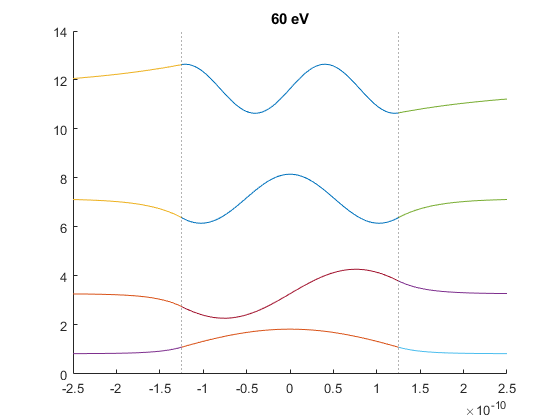

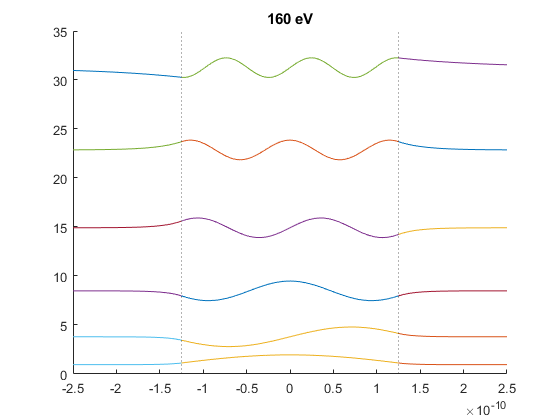



scale=5;

for kk=1:length(V)
    
    figure
    hold on

    %plot even solutions
    k=evenkKdiffV0{kk}(:,1);
    %Energy levels scaled in order plot to looks good
    E=h^2*k.^2/(2*me)/eV/scale;
    K=evenkKdiffV0{kk}(:,2);
    %Assuming the constant of cos is 1 and finding constant of exp
    %  boundary condition
    C=cos(k*a/2)./exp(-K*a/2);
    %plot inside the well, add E to symbolize energy levels in the well 
    fplot(cos(k*x)+E,[-a/2 a/2])
    %plot left of the well
    fplot(C.*exp(K*x)+E,[-a -a/2])
    %plot right of the well
    fplot(C.*exp(-K*x)+E,[a/2 a])
    
    
    %odd solutions 
    if ~isempty(oddkKdiffV0{kk})
        k=oddkKdiffV0{kk}(:,1);
        E=h^2*k.^2/(2*me)/eV/scale;
        K=oddkKdiffV0{kk}(:,2);
        C=sin(-k*a/2)./exp(-K*a/2);
        fplot(sin(k*x)+E,[-a/2 a/2])
        fplot(C.*exp(K*x)+E,[-a -a/2])
        fplot(-C.*exp(-K*x)+E,[a/2 a])
    end
    
    xline([-a/2 a/2],':')
    title(strcat(num2str(V(kk)/eV),' eV'))
    
end